# Plotter

Ci-dessous des essais du 22/05/25

## Méthode évenementielle

clear all
close all
folder = 'classic';
base_path = '~/mecanum/csv/';

### Trajectoires

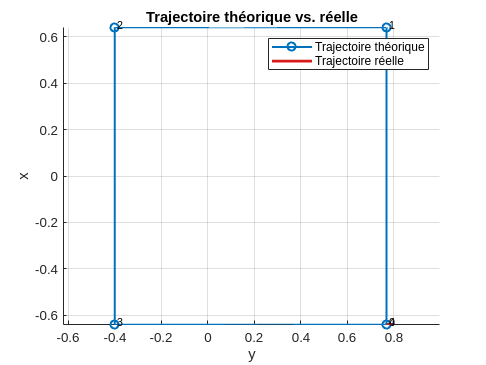

warning('off', 'all');

% === Lire le fichier ===
filename = fullfile(base_path, folder, 'distributed_barycenter_logger.csv');
lines = readlines(filename);

% Extraire le type de trajectoire depuis la première ligne
trajectory_type_line = lines(1);
trajectory_type = strtrim(extractAfter(trajectory_type_line, 'trajectory_type:'));

% Lire les données de trajectoire (en ignorant les 2 premières lignes)
data = readtable(filename);

% === Variables réelles (mesurées) ===
x_real = data.x;
y_real = data.y;

% === Trajectoire théorique ===
switch lower(trajectory_type)
    case 'eight'
        a = 1.0;
        b = 0.23;
        num_points = 16;
        start_x = -0.64;
        start_y = -0.77;

        X_th = zeros(num_points + 2, 1);
        Y_th = zeros(num_points + 2, 1);

        X_th(1) = start_x;
        Y_th(1) = start_y;

        for i = 1:num_points-1
            t = 2 * pi * (i-1) / num_points;
            X_th(i+1) = a * sin(t);
            Y_th(i+1) = b * sin(2 * t);
        end

        X_th(end) = start_x;
        Y_th(end) = start_y;

    case 'rectangle'
        X_th = [-0.64;  0.64;  0.64; -0.64; -0.64];
        Y_th = [-0.77; -0.77; 0.4;  0.4;  -0.77];

    otherwise
        error("Type de trajectoire inconnu : %s", trajectory_type);
end

% === Tracé de la trajectoire ===
figure;
hold on; grid on; axis equal;

plot(-Y_th, X_th, '-o', 'LineWidth', 1.5, 'MarkerSize', 6, 'DisplayName', 'Trajectoire théorique');
for i = 1:length(X_th)
    text(-Y_th(i)+0.01, X_th(i)+0.01, num2str(i-1), 'FontSize', 8);
end

plot(-y_real, x_real, '-', 'Color', [0.85 0.1 0.1], 'LineWidth', 2, 'DisplayName', 'Trajectoire réelle');
xlabel('y');
ylabel('x');
title('Trajectoire théorique vs. réelle');
legend;

Note : Dans le programme, on considère un point comme étant atteint si le barycentre de l'essaim est à 5cm de la cible, d'où les légers écarts avec les points-cibles.

### Distances

Ligne grise verticale : envoi d'un nouveau point-destination.

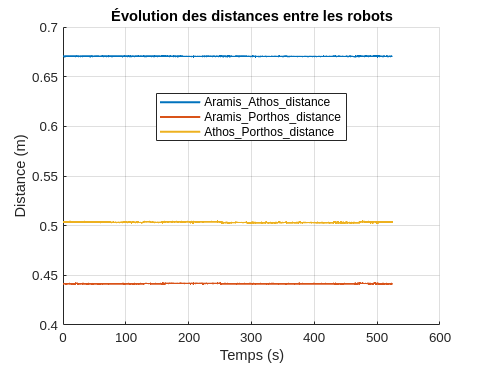

warning('off', 'all');

% === Paramètres ===
fichier_distance = fullfile(base_path, folder, 'distributed_distance_logger.csv');
fichier_trajectoire = fullfile(base_path, folder, 'distributed_goal_point_logger.csv');

% === Lecture du fichier des distances ===
data = readtable(fichier_distance);
timestamps_absolute = datetime(data{:, 1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
timestamps = seconds(timestamps_absolute - timestamps_absolute(1));  % temps relatif en secondes

% === Lecture du fichier de trajectoire ===
trajectoire = readtable(fichier_trajectoire);
timestamps_points_absolute = datetime(trajectoire{:, 1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
timestamps_points = seconds(timestamps_points_absolute - timestamps_absolute(1));  % même base temporelle

% === Tracé des distances ===
figure;
hold on;
grid on;

% Tracer chaque courbe de distance
for i = 2:width(data)
    nom_distance = data.Properties.VariableNames{i};
    valeurs = data{:, i};
    
    plot(timestamps, valeurs, 'DisplayName', strrep(nom_distance, '_', '\_'), 'LineWidth', 1.5);
end

% === Ajout des lignes verticales pour chaque point de trajectoire ===
yl = ylim;  % Limites verticales du graphe
for i = 2:length(timestamps_points)
    xline(timestamps_points(i), 'k--', 'LineWidth', 1.2, 'Alpha', 0.4, 'HandleVisibility', 'off');
end

xlabel('Temps (s)');
ylabel('Distance (m)');
title('Évolution des distances entre les robots');
legend('Location', 'best');

On note que les distances varient au lancement de l'algorithme, puis les robots convergent vers leurs positions voulues dans la formation (distance inter-robot relativement constante après que le premier point soit atteint)

### Commandes

%% Plotter : Visualisation des timestamps de commandes pour plusieurs robots

% Dossier contenant les CSV
files = dir(fullfile(base_path,folder, '*_cmd_vel_rate.csv'));

robot_names = {};
timestamp_counts = [];
timestamp_data = containers.Map;
dt_stats = containers.Map;

%% Lecture des fichiers de commandes
for i = 1:length(files)
    filename = fullfile(base_path,folder, files(i).name);
    data = readtable(filename, 'ReadVariableNames', false, 'Delimiter', ',');
    
    % Conversion des timestamps en datetime
    timestamps = datetime(data{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');

    % Nom du robot (avant le suffixe)
    robot_name = extractBefore(files(i).name, '_cmd_vel_rate.csv');
    robot_names{end+1} = robot_name;

    % Temps relatif (temps 0 = premier timestamp)
    timestamps_rel = seconds(timestamps - timestamps(1));
    timestamp_data(robot_name) = timestamps_rel;
    timestamp_counts(end+1) = numel(timestamps_rel);

    % Étude statistique du delta t
    delta_t = seconds(diff(timestamps));
    stats.mean = mean(delta_t);
    stats.std = std(delta_t);
    stats.min = min(delta_t);
    stats.max = max(delta_t);
    dt_stats(robot_name) = stats;

    % Affichage dans la console
    fprintf('\nRobot: %s\n', robot_name);
    fprintf('  N = %d commandes\n', numel(timestamps));
    fprintf('  Δt moyen    : %.4f s\n', stats.mean);
    fprintf('  Δt min      : %.4f s\n', stats.min);
    fprintf('  Δt max      : %.4f s\n', stats.max);
    fprintf('  Δt ec type  : %.4f s\n', stats.std);
end

Error using datetime (line 667)
Unable to convert 'timestamp' to datetime using the format 'yyyy-MM-dd'T'HH:mm:ss.SSSSSS'.


%% Figure 1 : Histogramme (bar chart)
figure;
bar(categorical(robot_names), timestamp_counts);
xlabel('Nom du robot');
ylabel('Nombre de commandes');
title('Nombre de commandes par robot');
grid on;

%% Lecture des points de trajectoire (pour les lignes verticales)

% Lire le CSV avec noms de colonnes
traj_data = readtable(fichier_trajectoire, 'Delimiter', ',', 'ReadVariableNames', true);
raw_timestamps = traj_data{:, 1};  % première colonne
goal_times = datetime(raw_timestamps, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
goal_times_rel = seconds(goal_times - goal_times(1));  % Temps relatif

%% Figure 2 : Chronogrammes par robot (subplots synchronisés)
figure;
n = length(robot_names);

% Fusionner tous les temps relatifs uniques
all_times = [];
for i = 1:n
    all_times = [all_times; timestamp_data(robot_names{i})];
end
all_times = unique(all_times);

% Subplots : chronogramme binaire pour chaque robot
for i = 1:n
    ax = subplot(n, 1, i);
    timestamps = timestamp_data(robot_names{i});
    y = ismember(all_times, timestamps);
    stem(all_times, y, 'Marker', 'none', 'LineWidth', 1.2);
    ylim([-0.1, 1.1]);
    ylabel(robot_names{i});
    if i == 1
        title('Chronogrammes des commandes');
    end
    if i < n
        set(gca, 'XTickLabel', []);
    else
        xlabel('Temps (s)');
    end
end

% Ajouter les lignes verticales pour les changements de consigne
for i = 1:n
    subplot(n, 1, i);
    hold on;
    for t = goal_times_rel'
        xline(t, '--r', 'LineWidth', 1);
    end
end